%%read dataset
traindata = readtable("train.csv");
testdata = readtable("test.csv");

%%if only consider 0_male and 1_female we can get the accuracy 0.7868
% disp(grpstats(traindata(:,{'Survived','Sex'}),'Sex'));
% gendermdl = grpstats(traindata(:,{'Survived','Sex'}),{'Survived','Sex'});
% accuracy = (gendermdl.GroupCount('0_male')+gendermdl.GroupCount('1_female'))/sum(gendermdl.GroupCount);
% disp(accuracy);

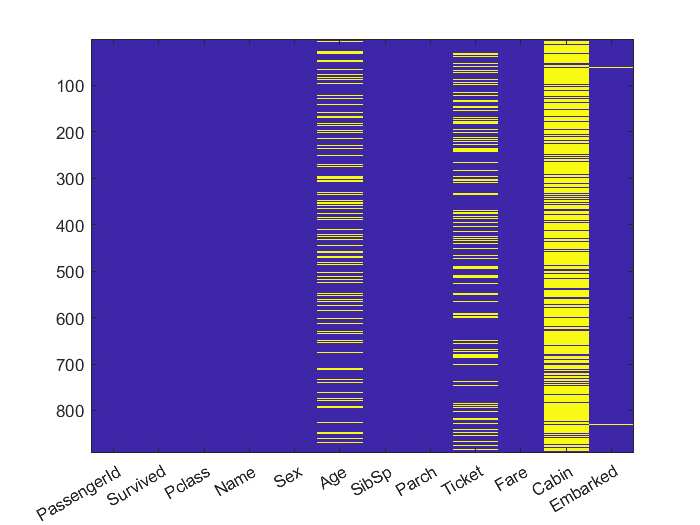

%%visualizing the NaN data
Xlabel_name = traindata.Properties.VariableNames;
figure;
imagesc(ismissing(traindata));
set(gca,'XTick',1:12,'XTickLabel',Xlabel_name);

%%after visualizing we find the feture 'age','Ticket','Cabin' and 'Embarked' lost
%%therefore we try to use 'Sex' and 'Pclass' two feature to compute naive
%%bayes
gendermdl = grpstats(traindata(:,{'Sex','Survived'}),{'Sex'})

gendermdl = 2×3 table
                 Sex        GroupCount    mean_Survived
              __________    __________    _____________

    male      {'male'  }       577           0.18891   
    female    {'female'}       314           0.74204   


p_gender(1,1) = gendermdl.mean_Survived(1);
p_gender(1,2) = 1 - gendermdl.mean_Survived(1);
p_gender(2,1) = gendermdl.mean_Survived(2);
p_gender(2,2) = 1 - gendermdl.mean_Survived(2);
Pclassmdl = grpstats(traindata(:,{'Pclass','Survived'}),{'Pclass'})

Pclassmdl = 3×3 table
         Pclass    GroupCount    mean_Survived
         ______    __________    _____________

    1      1          216           0.62963   
    2      2          184           0.47283   
    3      3          491           0.24236   


Pclass_num = unique(Pclassmdl.Pclass);
[row,~] = size(Pclass_num);
for i = 1 : row
    p_Pclass(i,1) = Pclassmdl.mean_Survived(i);
    p_Pclass(i,2) = 1 - Pclassmdl.mean_Survived(i);
end

cellans = cell(1+height(testdata),2);
stringname = {'PassengerId','Survived'};
cellans(1,:) = stringname;
for i = 1 : height(testdata)
    for j = 1 : row
        if(strcmp(testdata.Sex(i),'male') & testdata.Pclass(i) == j)
           p_survived = p_gender(1,1) * p_Pclass(j,1);
           p_unsurvived = p_gender(1,2) * p_Pclass(j,2);
        elseif(strcmp(testdata.Sex(i),'female') & testdata.Pclass(i) == j)
           p_survived = p_gender(2,1) * p_Pclass(j,1);
           p_unsurvived = p_gender(2,2) * p_Pclass(j,2);
        end
    end
    ans(i,1) = testdata.PassengerId(i);
    ans(i,2) = (p_survived > p_unsurvived);
end
cellans(2:1+height(testdata),:) = num2cell(ans);
xlswrite("submission.csv",cellans);